Данные

k = 7

k = 7

T = 0.5

T = 0.5000

Создаем передаточную функцию

sys = tf(k, [T,1])

sys =
 
      7
  ---------
  0.5 s + 1
 
Continuous-time transfer function.



Su = 1

Su = 1

Вычислим дисперсию:

Sy = (abs(freqresp(sys,0))^2)*Su

Sy = 49

Вычислим корреляционную функцию вектора состояния и выходного сигнала:

t = -5:0.1:5

t =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000


Rx = impulse(sys, t)

Rx =    14.0000
   11.4622
    9.3845
    7.6834
    6.2906
    5.1503
    4.2167
    3.4524
    2.8266
    2.3142


Ry = Sy*Rx

Ry =   686.0000
  561.6493
  459.8396
  376.4848
  308.2397
  252.3653
  206.6192
  169.1655
  138.5010
  113.3950


Вычисляем спектральную плотность вектора состояния и выходноо сигнала:

omega = -10:0.1:10

omega =   -10.0000   -9.9000   -9.8000   -9.7000   -9.6000   -9.5000   -9.4000   -9.3000   -9.2000   -9.1000   -9.0000   -8.9000   -8.8000   -8.7000   -8.6000   -8.5000   -8.4000   -8.3000   -8.2000   -8.1000   -8.0000   -7.9000   -7.8000   -7.7000   -7.6000   -7.5000   -7.4000   -7.3000   -7.2000   -7.1000   -7.0000   -6.9000   -6.8000   -6.7000   -6.6000   -6.5000   -6.4000   -6.3000   -6.2000   -6.1000   -6.0000   -5.9000   -5.8000   -5.7000   -5.6000   -5.5000   -5.4000   -5.3000   -5.2000   -5.1000


Sx = abs(freqresp(sys,omega)).^2*Su

Sx = Sx(:,:,1) =

    1.8846


Sx(:,:,2) =

    1.9214


Sx(:,:,3) =

    1.9592


Sx(:,:,4) =

    1.9982


Sx(:,:,5) =

    2.0383


Sx(:,:,6) =

    2.0796


Sx(:,:,7) =

    2.1221


Sx(:,:,8) =

    2.1660


Sx(:,:,9) =

    2.2112


Sx(:,:,10) =

    2.2578


Sx(:,:,11) =

    2.3059


Sx(:,:,12) =

    2.3555


Sx(:,:,13) =

    2.4067


Sx(:,:,14) =

    2.4595


Sx(:,:,15) =

    2.5141


Sx(:,:,16) =

    2.5705


Sx(:,:,17) =

    2.6288


Sx(:,:,18) =

    2.6890


Sx(:,:,19) =

    2.7513


Sx(:,:,20) =

    2.8157


Sx(:,:,21) =

    2.8824


Sx(:,:,22) =

    2.9514


Sx(:,:,23) =

    3.0228


Sx(:,:,24) =

    3.0969


Sx(:,:,25) =

    3.1736


Sx(:,:,26) =

    3.2531


Sx(:,:,27) =

    3.3356


Sx(:,:,28) =

    3.4212


Sx(:,:,29) =

    3.5100


Sx(:,:,30) =

    3.6023


Sx(:,:,31) =

    3.6981


Sx(:,:,32) =

    3.7977


Sx(:,:,33) =

    3.9013


Sx(:,:,34) =

    4.0090


Sx(:,:,35) =

    4.1211


Sx(:,:,36) =

    4.2378


Sx(:,:,37) =

    4.3594


Sx(:,

Sy = abs(freqresp(sys,omega)).^2*Su

Sy = Sy(:,:,1) =

    1.8846


Sy(:,:,2) =

    1.9214


Sy(:,:,3) =

    1.9592


Sy(:,:,4) =

    1.9982


Sy(:,:,5) =

    2.0383


Sy(:,:,6) =

    2.0796


Sy(:,:,7) =

    2.1221


Sy(:,:,8) =

    2.1660


Sy(:,:,9) =

    2.2112


Sy(:,:,10) =

    2.2578


Sy(:,:,11) =

    2.3059


Sy(:,:,12) =

    2.3555


Sy(:,:,13) =

    2.4067


Sy(:,:,14) =

    2.4595


Sy(:,:,15) =

    2.5141


Sy(:,:,16) =

    2.5705


Sy(:,:,17) =

    2.6288


Sy(:,:,18) =

    2.6890


Sy(:,:,19) =

    2.7513


Sy(:,:,20) =

    2.8157


Sy(:,:,21) =

    2.8824


Sy(:,:,22) =

    2.9514


Sy(:,:,23) =

    3.0228


Sy(:,:,24) =

    3.0969


Sy(:,:,25) =

    3.1736


Sy(:,:,26) =

    3.2531


Sy(:,:,27) =

    3.3356


Sy(:,:,28) =

    3.4212


Sy(:,:,29) =

    3.5100


Sy(:,:,30) =

    3.6023


Sy(:,:,31) =

    3.6981


Sy(:,:,32) =

    3.7977


Sy(:,:,33) =

    3.9013


Sy(:,:,34) =

    4.0090


Sy(:,:,35) =

    4.1211


Sy(:,:,36) =

    4.2378


Sy(:,:,37) =

    4.3594


Sy(:,


Ex = sum(Sx)* (omega(2)-omega(1))

Ex = 269.3744

Построим графики:

%Корреляционная функция вектора состояния
figure;
t=-5:0.1:0

t =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000


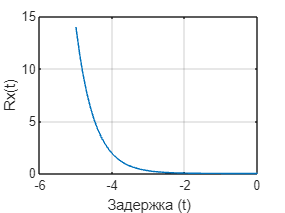

plot(t,Rx)
grid on
xlabel('Задержка (t)')
ylabel('Rx(t)')

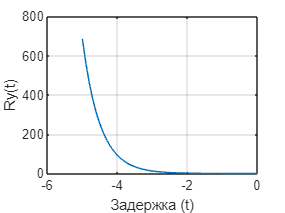


%Корреляционная функция выходного сигнала

figure;
plot(t,Ry)
grid on
xlabel('Задержка (t)')
ylabel('Ry(t)')

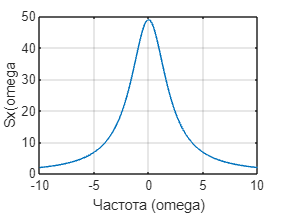


%Спектральная плотность вектора состояния
plot(omega, squeeze(Sx))
grid on
xlabel('Частота (omega)')
ylabel('Sx(omega')

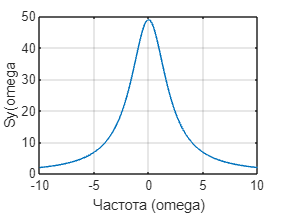


%Спектральная плотность выходного сигнала
plot(omega, squeeze(Sy))
grid on
xlabel('Частота (omega)')
ylabel('Sy(omega')

exp(-120)

ans = 7.6676e-53